# Partie B: Image compression

## B.1

La transformation en cosinus discrète (DCT) est l'une des méthodes de compression d'image avec perte. Cette méthode divise l'image en blocs de pixels et applique une transformation DCT à chaque bloc. Ensuite, les coefficients de la transformée DCT sont quantifiés, c'est-à-dire arrondis aux valeurs entières les plus proches en fonction d'un facteur de qualité déterminé. Plus le facteur de qualité est élevé, moins il y a de pertes d'informations, mais plus la taille de l'image compressée est grande. Le processus de décompression se fait dans le sens inverse. 

## B.2

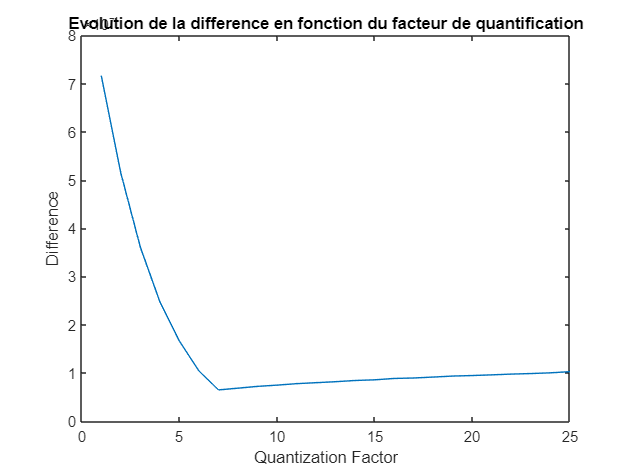

img_original = imread('Nature.bmp');
img_original_crop=img_original(1:680,:,:);
nom_source_bmp = 'Nature.bmp'; % Nom du fichier source BMP
nom_destination_bmp='Nature_c_d_2.bmp';
quant_factors = 1:25;


diff_array = zeros(1, length(quant_factors));

for i = 1:length(quant_factors)
    % Compression  
    main_compression(quant_factors(i), nom_source_bmp, 'compressed_image.jpg');
    
    % Decompression
    main_decompression('compressed_image.jpg', nom_destination_bmp);
    decompressed_img = imread(nom_destination_bmp);
    % Calcul de la différence 
    diff_array(i) = sum(abs(double(img_original_crop(:))-double(decompressed_img(:))));
end

% Affichage
plot(quant_factors, diff_array);
xlabel('Quantization Factor');
ylabel('Difference');
title('Evolution de la difference en fonction du facteur de quantification');

## B.3

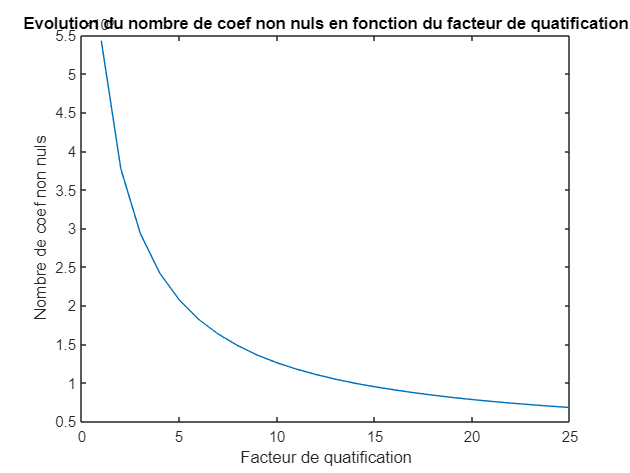

nom_source_bmp = 'Nature.bmp'; % Nom du fichier source BMP
coeffs_non_nuls_liste = zeros(1,25);
nom_destination_jpg='Nature_b3.jpg';
for coef=1:25
    %utilisation de la fonction main_compression_count créée pour calculer
    %les coefficients non nuls
    [coeffs_non_nuls, duree_traitement] = main_compression_count(coef, nom_source_bmp, nom_destination_jpg);
    coeffs_non_nuls_liste(coef)=coeffs_non_nuls;
end

%Affichage
figure,
plot(1:25,coeffs_non_nuls_liste)
xlabel('Facteur de quatification')
ylabel("Nombre de coef non nuls")
title("Evolution du nombre de coef non nuls en fonction du facteur de quatification")

## B.4

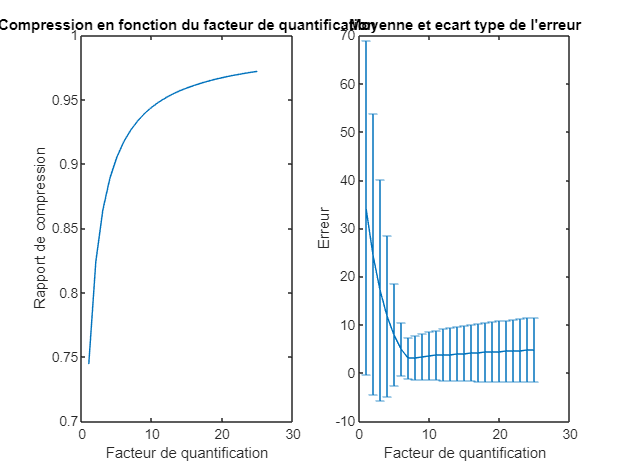

quantization_range = 1:25;
nom_source_bmp = 'Nature.bmp'; % Nom du fichier source BMP
nom_destination_jpg='Nature_c_d_b4.jpg';
nom_destination_bmp='Nature_c_d_b4_bmp.bmp';
img_original = imread('Nature.bmp');
img_original_crop=img_original(1:680,:,:);
compression_rates = zeros(size(quantization_range));
mean_errors = zeros(size(quantization_range));
std_errors = zeros(size(quantization_range));
compressed_file_size=zeros(1,25);
nb_coef_nuls=zeros(1,25);
for i = 1:length(quantization_range)
    % Compression et calcul des coefs non nuls
    main_compression(quantization_range(i), nom_source_bmp, nom_destination_jpg);

    
    % Decompression et calcul des coefs non nuls
    [non_zero_coefficients,duree_traitement] = main_decompression_count(nom_destination_jpg, nom_destination_bmp);
    
    
    % Calcul du rapport de compression 
    compressed_file_size(i) = size(imread(nom_destination_bmp),1)*size(imread(nom_destination_bmp),2)*size(imread(nom_destination_bmp),3);
    nb_coef_nuls(i)= size(imread(nom_source_bmp),1)*size(imread(nom_source_bmp),2)*size(imread(nom_source_bmp),3)-coeffs_non_nuls_liste(i);
  
    compression_rates(i) = nb_coef_nuls(i) / compressed_file_size(i);
    
    % Calcul de l'erreur entre l'original et la l'image reconstruite
    original_image = double(img_original_crop);
    reconstructed_image = double(imread(nom_destination_bmp));
    error_image = original_image - reconstructed_image;
    mean_errors(i) = mean(abs(error_image(:)));
    std_errors(i)= std(abs(error_image(:)));
 
end

% Affichage
subplot(1, 2, 1);
plot(quantization_range, compression_rates);
xlabel('Facteur de quantification');
ylabel('Rapport de compression');
title('Compression en fonction du facteur de quantification');

% Affichage
subplot(1, 2, 2);
errorbar(quantization_range, mean_errors, std_errors);
xlabel('Facteur de quantification');
ylabel('Erreur');
title("Moyenne et ecart type de l'erreur")

On remarque que le rapport de compression augmente avec le facteur de quantification, car plus le facteur de qualité est élevé, moins il y a de pertes d'informations, mais plus la taille de l'image compressée est grande. 

Pour l'erreur, elle dimininue fortement jusqu'au coefficient 7 puis stagne plus ou moins jusqu'au coefficient 25. De plus, l'écart type suit la même tendance à savoir: diminue jusqu'à 7 puis stagne. Cette diminution est lié au fait qu'un coefficient plus élevé traduit une qualité d'image supérieure donc une erreur moindre. En revanche, il est difficile d'expliquer la satgnation voire l'augmentation de l'erreur après le coefficient 7. Sans doute que cette méthode posséde une limite autour du coefficient 7. 

**Fonctions créées**

function [coeffs_non_nuls, duree_traitement] = main_compression_count(qualite, nom_source_bmp, nom_destination_jpg)

%Initialisation de l'horloge
temps_debut = cputime;

%lecture de l'image source
imageBMP = lecture_image_bmp(nom_source_bmp);

%conversion de la matrice avec l'application de la DCT sur les blocs 8x8 de l'image bitmap source
imageJPG = conversion_spatial_frequantiel(imageBMP, qualite);

%ecriture de l'image DCTs dans un fichier
ecriture_jpg(imageJPG, nom_destination_jpg, qualite);
coeffs_non_nuls = nnz(imageJPG);

%terminaison de l'horloge à la fin du traitement
temps_fin = cputime;

duree_traitement = temps_fin - temps_debut;
end



function[coeffs_non_nuls, duree_traitement]=main_decompression_count(nom_source_jpg, nom_destination_bmp)

temps_debut = cputime;

%lecture jpg
[JPG,qualite] = lecture_jpg(nom_source_jpg);

%reconversion de la matrice : application de la i-DCT sur la matrice
BMP = conversion_frequentiel_spatial(JPG,qualite);
coeffs_non_nuls = nnz(BMP);
%ecriture de la matrice traitee par la i-DCT dans un fichier
ecriture_bmp(BMP, nom_destination_bmp);

temps_fin = cputime;
duree_traitement = temps_fin - temps_debut;
end

